# Gráficas bidimensionales

## Graficación básica con función `plot`

Una vez definidos los vectores de valores **x** y valores **y** es posible crear una gráfica *x-y* mediante la función `plot`.

- El primer argumento de la función `plot` serán los valores para el eje **x**.

- El segundo argumento de la función `plot` serán los valores para **y**.

x = 0:2:18;
y = [0 .33 4.13 6.29 6.85 11.19 13.19 13.96 16.33 18.17];

plot(x,y)

**Aclaración**: No necesariamente se deben llamar **x** y **y**, respectivamente, a los argumentos de la función `plot`. Lo importante es entender cómo funciona la función.

### Títulos, etiquetas y retículas

También es de suma importancia como ingenieros añadir los nombres y las unidades a la gráfica que se genere para un mayor entendimiento de esta.

Las siguientes funciones y comandos nos ayudan a detallar mejor una gráfica.

- `title`: añade un título.

- `xlabel`: añade un nombre al eje **x**.

- `ylabel`: añade un nombre al eje **y**.

- `grid`: activa la retícula, o rejilla.

plot(x,y)
title 'Experimento de laboratorio 1'    % Título.
xlabel 'Tiempo (s)'                     % Nombre del eje x.
ylabel 'Distancia (m)'                  % Nombre del eje y.
grid on                                 % Activar retícula.

Ideas importantes:

- Los títulos, etiquetas y retícula siempre van después de definir el `plot`.

- La cadena (**string**) es una lista de caracteres encerrados por apóstrofes (comillas simples) o comillas.

- La cadena puede ir entre apóstrofes.

- La cadena puede ir entre comillas.

Sin embargo, si se quiere incluir un apóstrofe dentro de la cadena se escriben 2 apóstrofes.

También es posible definir lo anterior entre paréntesis para mayor entendimiento, pero ya es cuestión de gustos.

### Creación de gráficas múltiples

Si se quiere realizar más de una gráfica se puede utilizar la siguiente función y comando, respectivamente.

#### Función `figure`

La función `figure` permite crear otra figura para una gráfica y así no sobreescribir la anteior. Es decir, abrirá una ventana para la figura 1 y otra para la figura 2 en lugar de sobreescribir la gráfica 1 con la 2.

**Nota:** Generalmente esto es más útil cuando se trabaja con scripts .m que con live scripts .mlx porque los scripts .m ejecutan los procesos y los muestran en la ventana de comandos, mientras que los live scripts .mlx tienen su propia zona de impresión de resultados, por lo que no es necesario crear figuras.

clear

x1 = 0:20;
y1 = x1;
y2 = x1.^2;

figure(1)       % Figura 1 que aparecerá en una ventana.
plot(x1,y1)

figure(2)       % Figura 2 que aparecerá en otra ventana.
plot(x1,y2)

#### Comando `pause`

El comando `pause` detiene la ejecución del programa hasta que se oprima alguna tecla. O si se quiere mostrar por una cantidad de segundos basta con darle como argumento esa cantidad.

clear

x1 = 0:20;
y1 = x1;
y2 = x1.^2;

plot(x1,y1)
pause

plot(x1,y2)

**Nota:** Tomar en cuenta las mismas consideraciones que se hicieron para la función `figure`.

### Gráficas con más de una línea con comando `hold`

Por defecto, la generación de un nuevo `plot` sobreescribirá al anterior, sin embargo, con el comando `hold` las gráficas se almacenan en capas en una sola.

clear

x = 0:pi/100:2*pi;
y1 = (cos(x*4));
plot(x,y1)

y2 = (sin(x));
hold on
plot(x,y2)

hold off

MATLAB seguirá asignando capas a una misma gráfica hasta que se cancele el comando `hold`, es decir, se escriba `hold off`.

Algo interesante es que no necesariamente son vectores fila/columna los argumentos de la función `plot`, también pueden ser matrices.

**Foma normal**

clear

x = 0:pi/100:2*pi;
y1 = cos(x)*2;
y2 = cos(x)*3;
y3 = cos(x)*4;
y4 = cos(x)*5;
plot(x,y1,x,y2,x,y3,x,y4)

**Con matriz**

z = [
    y1
    y2
    y3
    y4
    ];
plot(x,z)

### Función `peaks`

La función `peaks` es una función de dos variables que produce datos muestra útiles para demostrar algunas funciones de graficación. 

- Los gráficos se crean al escalar y trasladar distribuciones gaussianas.

Se puede usar `peaks`, por ejemplo, para demostrar la pontencia de usar como argumento de la función `plot` una matriz.

clear

plot(peaks(100))

### Gráficas de arreglos complejos

Si se ingresa a la función `plot` como argumento un arreglo de números complejos se tiene lo siguiente:

- Si el argumento es un único vector fila/columna de números complejos se representará en el eje **x** la parte real y en el eje **y** la parte imaginaria.

- Si se ingresan dos argumentos de números complejos, MATLAB tomará la parte real del primero para el eje **x** y la parte real del segundo para el eje **y**. Es decir, omitirá las partes imaginarias de ambos arreglos.

**Nota:** Para el segundo caso saldrá una advertencia detallado lo que ya se ha mencionado.

clear

A = [0+0i 1+2i 2+5i 3+4i];
plot(A)
title 'Gráfica de un sólo arreglo complejo'
xlabel 'Componente real'
ylabel 'Componente imaginario'

B = sin(A);
plot(A,B)
title 'Gráfica de dos arreglos complejos'
xlabel 'Componente real del arreglo A'
ylabel 'Componente real del arreglo B'

## Línea, color y estilo de marca

MATLAB muestra la apariencia de las gráficas por defecto, sin embargo, es posible modificarlas al gusto de cada uno.

clear

x = 1:10;
y = [58.8 63.8 64.2 67.3 71.5 88.3 90.1 90.6 89.5 90.4];
plot(x,y, ':ok')
% Plot con línea punteada, tipo de punto (marcador) 'o' y color negro.

Otra forma de escribir el mismo `plot` pero detallando a qué se refiere cada parámetro es sería:

A continuación se detallan los indicadores de cada especificación:

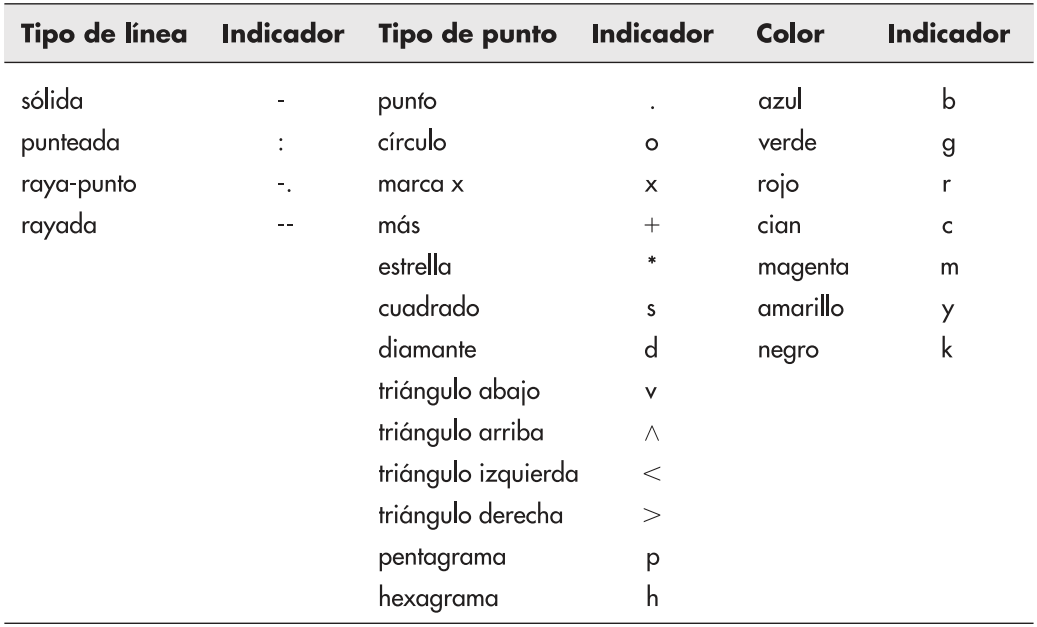

Sólo es cuestión de memorizar los tipos de línea, color, marcadores, etc.; de los cuales dispone MATLAB para hacer un `plot `de manera resumida. Sin embargo, como se observa en el código de ejemplo, también es posible definir la apariencia de manera detallada.

Por otra parte, si se realizan varias gráficas en una sola (en capas) se deben detallar las especificaciones para cada una después de definirlas.

clear

x = 1:10;
y = [58.8 63.8 64.2 67.3 71.5 88.3 90.1 90.6 89.5 90.4];
plot(x,y,':ok',x,y*2,'--xr',x,y/2,'-b')

**Nota:** Estas son 3 de todas las especificaciones que se pueden modificar sobre la apariencia. Para mayor información se recomienda revisar la documentación.

## Escalamiento de ejes y anotaciones

Si se desea controlar la escala de la gráfica o añadir anotaciones, en la siguiente tabla se detallan las funciones (también está añadida en las tablas de resumen).

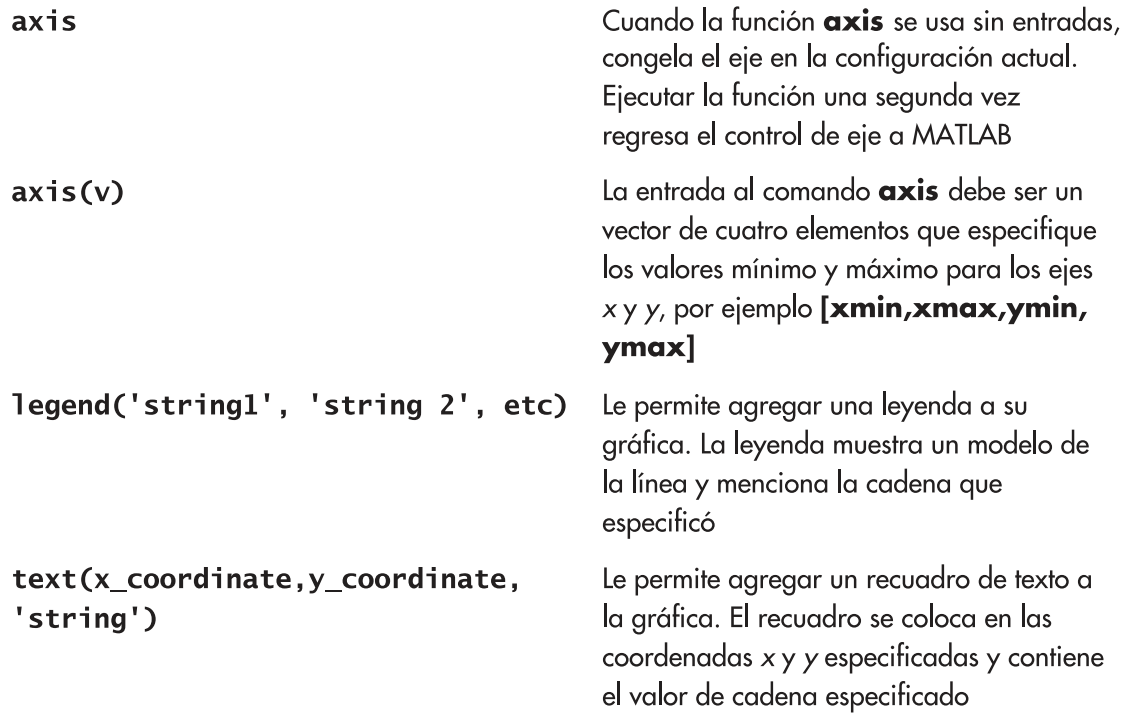

clear

x = 1:10;
y = [58.8 63.8 64.2 67.3 71.5 88.3 90.1 90.6 89.5 90.4];
plot(x,y,':ok',x,y*2,'--xr',x,y/2,'-b')
title('Ejemplo de múltiples gráficas en una sola')
xlabel('Eje x')
ylabel('Eje y')

% Escalamiento de ejes y anotaciones
legend('Línea 1','Línea 2','Línea 3')
text(1,100,'Esta es una anotación con el comando text.')
axis([0,11,0,200])

## Uso de símbolos especiales (lenguaje LaTeX)

Es posible utilizar letras griegas en las etiquetas ubicando una diagonal inversa (`\`) antes del nombre de la letra,

lo cual devolvería el título $\alpha \beta \gamma$.

A su vez, para crear superíndices se utiliza llaves,

lo cual devolvería $x^2$.

MATLAB tiene la habilidad de crear expresiones matemáticas más complicadas para usar como títulos, etiquetas de ejes y otras cadenas de texto, al usar el lenguaje formateador de textos TEX.

**Recomendación:** Aprender las bases de LaTeX al menos puede ser de gran utilidad.

## Tablas de resumen

Se hace hincapié en que las siguientes tablas son de resumen. Esto se debe a que cada fución o comando dispone de más características internas por sí mismo. Por ejemplo, para la leyenda (`legend`) también se puede modificar su ubicación en la gráfica y su orientación.

Aunque suene algo repetitivo (porque es muy importante), para mayor detalle revisar la documentación.

### Funciones de graficación básicas

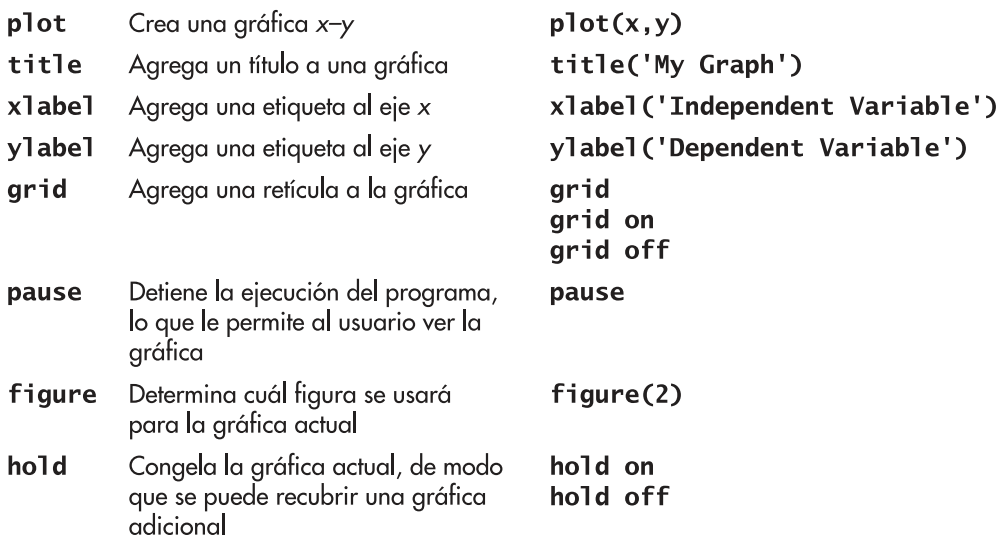

### Opciones de línea, marca y color

### Escalamiento de ejes y anotaciones